% Obstructed Data

% Stationary data from GPS Sensor:

stationary = rosbag("Stationary.bag");
stationarySelectTopic = select(stationary, "Topic", "gps_data_lab2");
s_msgs = readMessages(stationarySelectTopic,"DataFormat","struct");

s_seq = cellfun(@(m) double(m.Header.Seq),s_msgs);
s_Latitude = cellfun(@(m) double(m.Latitude),s_msgs);
s_Longitude = cellfun(@(m) double(m.Longitude),s_msgs);
s_Altitude = cellfun(@(m) double(m.Altitude),s_msgs);
s_UTMEasting = cellfun(@(m) double(m.UtmEasting),s_msgs);
s_UTMNorthing = cellfun(@(m) double(m.UtmNorthing),s_msgs);
s_Zone = cellfun(@(m) double(m.Zone),s_msgs);
s_Letter = cellfun(@(m) double(m.Letter),s_msgs);

s_mean_utme = mean(s_UTMEasting)

s_mean_utme = 3.2761e+05

s_mean_utmn = mean(s_UTMNorthing)

s_mean_utmn = 4.6893e+06

s_mean_alt = mean(s_Altitude)

s_mean_alt = 14.0594

s_std_utme = std(s_UTMEasting)

s_std_utme = 0.0980

s_std_utmn = std(s_UTMNorthing)

s_std_utmn = 0.3858

s_std_alt = std(s_Altitude)

s_std_alt = 0.9879

s_var_utme = var(s_UTMEasting)

s_var_utme = 0.0096

s_var_utmn = var(s_UTMNorthing)

s_var_utmn = 0.1489

s_var_alt = var(s_Altitude)

s_var_alt = 0.9759

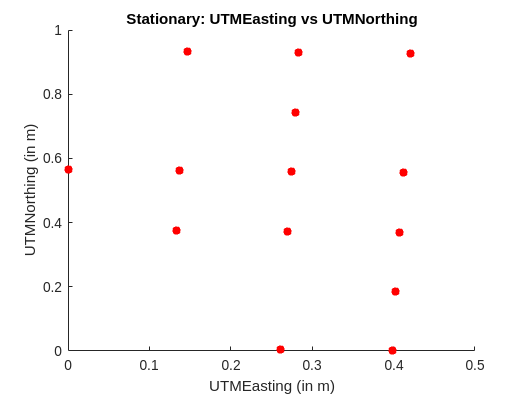


s_UTMEastingScaled = s_UTMEasting - min(s_UTMEasting);
s_UTMNorthingScaled = s_UTMNorthing - min(s_UTMNorthing);

figure(1)
scatter(s_UTMEastingScaled, s_UTMNorthingScaled, "filled", "r");
title("Stationary: UTMEasting vs UTMNorthing");
xlabel("UTMEasting (in m)");
ylabel("UTMNorthing (in m)");

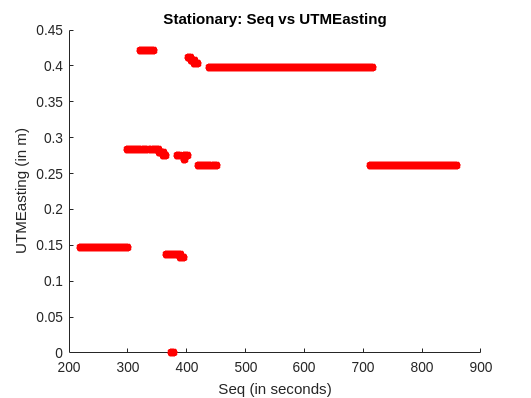


figure(2)
scatter(s_seq, s_UTMEastingScaled, "filled", "r");
title("Stationary: Seq vs UTMEasting");
xlabel("Seq (in seconds)");
ylabel("UTMEasting (in m)");

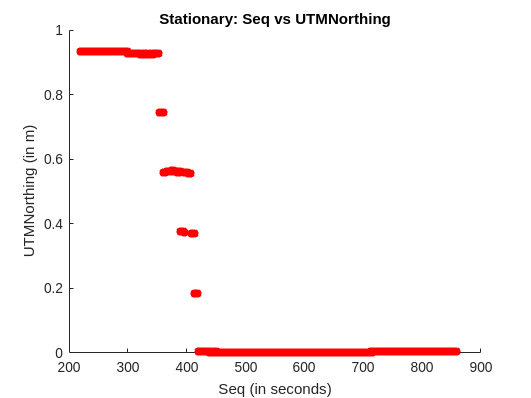


figure(3)
scatter(s_seq, s_UTMNorthingScaled, "filled", "r");
title("Stationary: Seq vs UTMNorthing");
xlabel("Seq (in seconds)");
ylabel("UTMNorthing (in m)");

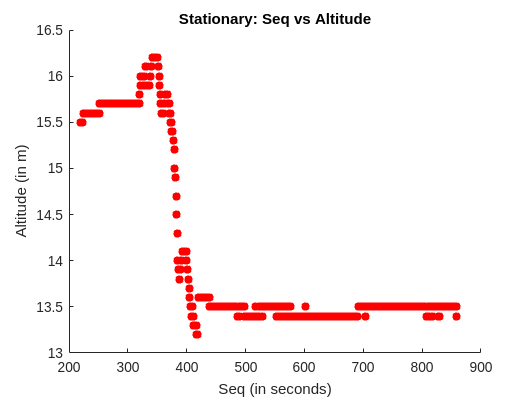


figure(4)
scatter(s_seq, s_Altitude, "filled", "r");
title("Stationary: Seq vs Altitude");
xlabel("Seq (in seconds)");
ylabel("Altitude (in m)");


s_coeffUTM = polyfit(s_UTMEasting, s_UTMNorthing, 1);
s_UTMNorthingFit = polyval(s_coeffUTM, s_UTMEasting);

s_error = zeros(size(s_UTMNorthing));

for i = 1:size(s_UTMNorthing)
    s_error(i) = abs(s_UTMNorthingFit(i) - s_UTMNorthing(i));
end

s_error_min = min(s_error)

s_error_min = 0.0382

s_error_max = max(s_error)

s_error_max = 0.9307

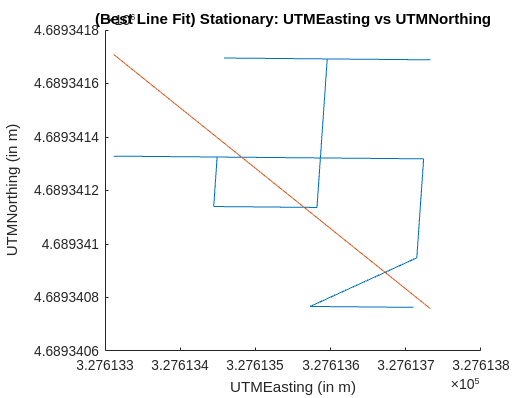


figure(5)
hold on
plot(s_UTMEasting, s_UTMNorthing)
plot(s_UTMEasting, s_UTMNorthingFit)
title("(Best Line Fit) Stationary: UTMEasting vs UTMNorthing");
xlabel("UTMEasting (in m)");
ylabel("UTMNorthing (in m)");
hold off


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

stationary = rosbag("Move.bag");
stationarySelectTopic = select(stationary, "Topic", "gps_data_lab2");
msgs = readMessages(stationarySelectTopic,"DataFormat","struct");

seq = cellfun(@(m) double(m.Header.Seq),msgs);
Latitude = cellfun(@(m) double(m.Latitude),msgs);
Longitude = cellfun(@(m) double(m.Longitude),msgs);
Altitude = cellfun(@(m) double(m.Altitude),msgs);
UTMEasting = cellfun(@(m) double(m.UtmEasting),msgs);
UTMNorthing = cellfun(@(m) double(m.UtmNorthing),msgs);
Zone = cellfun(@(m) double(m.Zone),msgs);
Letter = cellfun(@(m) double(m.Letter),msgs);

mean_utme = mean(UTMEasting)

mean_utme = 3.2763e+05

mean_utmn = mean(UTMNorthing)

mean_utmn = 4.6893e+06

mean_alt = mean(Altitude)

mean_alt = 15.0848

std_utme = std(UTMEasting)

std_utme = 8.1010

std_utmn = std(UTMNorthing)

std_utmn = 4.0838

std_alt = std(Altitude)

std_alt = 0.6007

var_utme = var(UTMEasting)

var_utme = 65.6269

var_utmn = var(UTMNorthing)

var_utmn = 16.6773

var_alt = var(Altitude)

var_alt = 0.3608

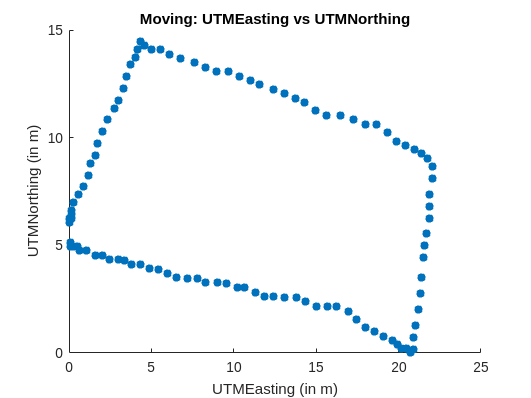


UTMEastingScaled = UTMEasting - min(UTMEasting);
UTMNorthingScaled = UTMNorthing - min(UTMNorthing);

figure(6)
scatter(UTMEastingScaled, UTMNorthingScaled, "filled");
title("Moving: UTMEasting vs UTMNorthing");
xlabel("UTMEasting (in m)");
ylabel("UTMNorthing (in m)");

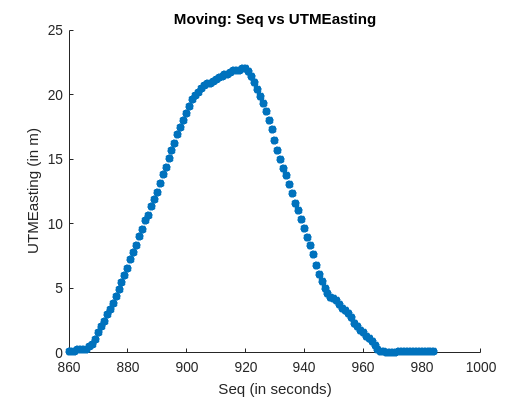


figure(7)
scatter(seq, UTMEastingScaled, "filled");
title("Moving: Seq vs UTMEasting");
xlabel("Seq (in seconds)");
ylabel("UTMEasting (in m)");

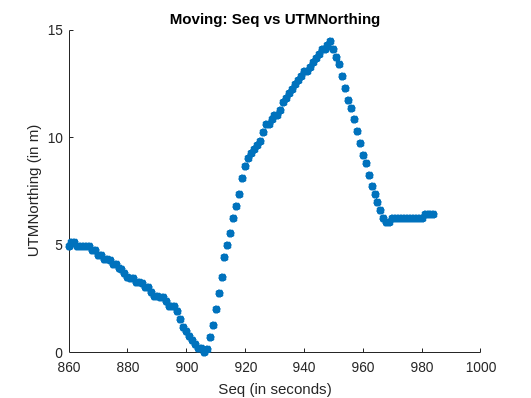


figure(8)
scatter(seq, UTMNorthingScaled, "filled");
title("Moving: Seq vs UTMNorthing");
xlabel("Seq (in seconds)");
ylabel("UTMNorthing (in m)");

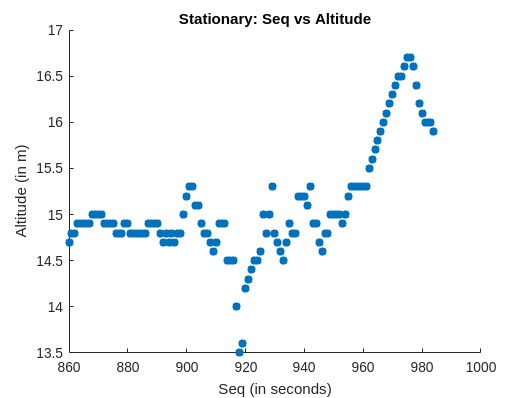


figure(9)
scatter(seq, Altitude, "filled");
title("Stationary: Seq vs Altitude");
xlabel("Seq (in seconds)");
ylabel("Altitude (in m)");


coeffUTM = polyfit(UTMEasting, UTMNorthing, 1);
UTMNorthingFit = polyval(coeffUTM, UTMEasting);

coeffAlt = polyfit(seq, Altitude, 1);
AltitudeFit = polyval(coeffAlt, seq);

error = zeros(size(UTMNorthing));

for i = 1:size(UTMNorthing)
    error(i) = abs(UTMNorthingFit(i) - UTMNorthing(i));
end

error_min = min(error)

error_min = 0.0557

error_max = max(error)

error_max = 7.2370

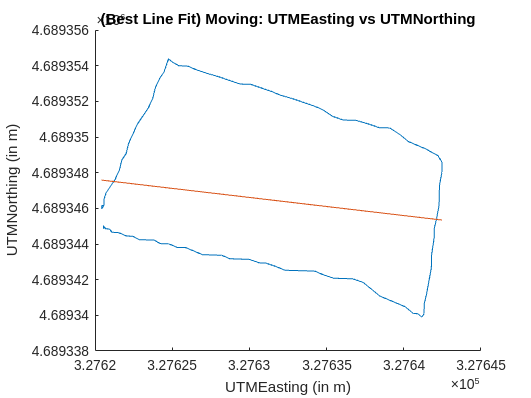


figure(10)
hold on
plot(UTMEasting, UTMNorthing)
plot(UTMEasting, UTMNorthingFit)
title("(Best Line Fit) Moving: UTMEasting vs UTMNorthing");
xlabel("UTMEasting (in m)");
ylabel("UTMNorthing (in m)");
hold off